clear;
clc;
x_ =[1.3 1.3 1.6 1.6 1.9 1.9]';
y_= [0.6200860 0.6200860 0.4554022 0.4554022 0.2818186 0.2818186]';
z_= [-0.5220232 -0.5220232 -0.5698959 -0.5698959 -0.5811571 -0.5811571]';
y = y_;
syms x;
P= zeros(length(y));
P(:,1)=y';

%%% DETERMINAMOS LA MATRIZ DE DIFERENCIAS DIVIDIDAS  DE HERMITE %%%
k=1;
for i=2 : length(y) 
    for j=i : length(y)   
          if(y(j-1,1)==y(j,1))
             P(j,i)=z_(j) ;
          else
             P(j,i)= (y(j)-y(j-1))/(x_(j)-x_(j-k)) ; 
          end
    end
   k=i; 
   y=P(:,i);
end
P

P =     0.6201         0         0         0         0         0
    0.6201   -0.5220         0         0         0         0
    0.4554   -0.5489   -0.0897         0         0         0
    0.4554   -0.5699   -0.0698    0.0664         0         0
    0.2818   -0.5786   -0.0291    0.0680    0.0027         0
    0.2818   -0.5812   -0.0085    0.0686    0.0010   -0.0028



%%% EXTRACCION DE LOS COEFICIENTES DE LAS DIFERENCIAS DIVIDIDAS %%%
coef=[1;3];
for i=1:length(y)
    coef(i)=P(i,i);
    
end
coef

coef =     0.6201
   -0.5220
   -0.0897
    0.0664
    0.0027
   -0.0028



%%% GENERAMOS LA MATRIZ SIMBOLICA DE X - CADA ELEMENTO DE x %%%
 symss={'yy';'y'};
 matrixx=str2sym(symss);
for i=1:length(y)
       matrixx(i)=x-x_(i);
end
matrixx;
% matrixx(1)*matrixx(2,:);

%%% GENERAMOS LAS VARIABLES DE MULTIPLICACION DE LOS COEFICIENTES %%%
MAT_2=matrixx;
for i=1:length(y)-1
      MAT_2(i+1)=prod(matrixx(1:i,1));
end
MAT_2(1)=1;
matrixx

$$matrixx = \left(\begin{array}{c} x-\frac{13}{10}\\ x-\frac{13}{10}\\ x-\frac{8}{5}\\ x-\frac{8}{5}\\ x-\frac{19}{10}\\ x-\frac{19}{10} \end{array}\right)$$

MAT_2

$$MAT\_2 = \left(\begin{array}{c} 1\\ x-\frac{13}{10}\\ {\left(x-\frac{13}{10}\right)}^{2}\\ \left(x-\frac{8}{5}\right)\,{\left(x-\frac{13}{10}\right)}^{2}\\ {\left(x-\frac{8}{5}\right)}^{2}\,{\left(x-\frac{13}{10}\right)}^{2}\\ {\left(x-\frac{8}{5}\right)}^{2}\,{\left(x-\frac{13}{10}\right)}^{2}\,\left(x-\frac{19}{10}\right) \end{array}\right)$$

%% MATRIZ DE FACTORES %%%
M_F =vpa(simplify(sum(coef.*MAT_2)),8) 

$$M\_F = -0.0027746914\,x^{5}+0.02403179\,x^{4}-0.01455608\,x^{3}-0.23521617\,x^{2}-0.0082292235\,x+1.0019441$$

char(M_F)

ans = '0.02403179*x^4 - 0.23521617*x^2 - 0.01455608*x^3 - 0.0082292235*x - 0.0027746914*x^5 + 1.0019441'

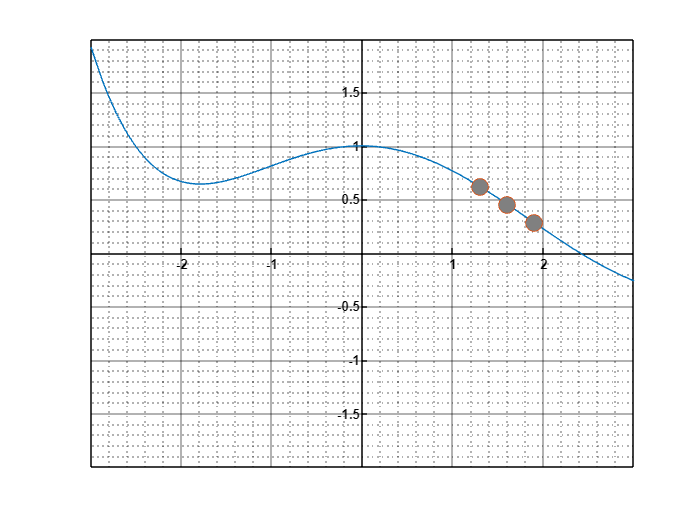


grid on; 
grid minor;
hold all;

% Configurar el eje
ax = gca;
ax.XAxisLocation = 'origin'; % Eje X en el origen
ax.YAxisLocation = 'origin'; % Eje Y en el origen

% Ajustar espacio entre ticks y mostrar valores
ax.XTick = -2:1:2; % Valores para el eje X (de -10 a 10, paso 2)
ax.YTick = -2:0.5:2; % Valores para el eje Y (de -10 a 10, paso 2)

% Mostrar etiquetas en los ejes
ax.XColor = 'k'; % Color del eje X (negro)
ax.YColor = 'k'; % Color del eje Y (negro)
ax.TickLength = [0.01, 0.01]; % Tamaño de las marcas en los ejes
ax.FontSize = 8; % Tamaño de la fuente de las etiquetas
ax.FontWeight = 'bold';
% Configurar grillas mayores y menores
ax.GridColor = [0 0 0]; % Color negro para la grilla mayor
ax.GridAlpha = 0.4; % Transparencia de la grilla mayor (0 = invisible, 1 = opaco)
ax.MinorGridColor = [0 0 0]; % Color negro para la grilla menor
ax.MinorGridAlpha = 0.4; % Transparencia de la grilla menor
axis([-3 3 -2 2]);
% Añadir un marco negro
ax.Box = 'on'; % Activa el marco
ax.LineWidth = 0.1; % Grosor del marco
ax.Color = 'none'; % Fondo transparente, si es necesario
% Graficar función y puntos
fplot(M_F, [-3, 3]); % Dibuja la función M_F en el rango de -10 a 10
plot(x_, y_,'o','MarkerFaceColor',[0.5,0.5,0.5],'MarkerSize',10); % Dibuja los puntos especificados
axis([-3 3 -2 2]);

x=1.5

x = 1.5000

eval(M_F)

ans = 0.5118

EJEMPLO DE LIBRO DE BURDEN.

x_ =[1.3 1.3 1.6 1.6 1.9 1.9]';

y_= [0.6200860 0.6200860 0.4554022 0.4554022 0.2818186 0.2818186]';

z_= [-0.5220232 -0.5220232 -0.5698959 -0.5698959 -0.5811571 -0.5811571]';

EJEMPLO DE YOUTUBE.